---

title: "PEP_wp4_beh"

output: html_document

date: "2023-12-15"

--- house keeping ---

% clear workspace
clear;
clc;

% set working directory
wd = 'C:/Users/JLU-SU/OneDrive - Justus-Liebig-Universität Gießen/Dokumente/GitHub/pep_wp4_analysis';
cd(wd);

function_folder = fullfile(pwd, 'functions')

function_folder = 'C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_analysis\functions'

addpath(function_folder)

--- loading files ---

% details of subjects
d.subNums = [101, 102, 103, 104, 105, 106, 109, 110, 112, 114, 115, 116, 117, 118, 119, 120, 121, 122, 123, 124, 125, 126]; 
d.n = length(d.subNums);

% add scene categories
d.categories = {'bathroom', 'kitchen'};

% load files using costum function
d = load_files(d);

Loaded: 101
Loaded: 102
Loaded: 103
Loaded: 104
Loaded: 105
Loaded: 106
Loaded: 109
Loaded: 110
Loaded: 112
Loaded: 114
Loaded: 115
Loaded: 116
Loaded: 117
Loaded: 118
Loaded: 119
Loaded: 120
Loaded: 121
Loaded: 122
Loaded: 123
Loaded: 124
Loaded: 125
Loaded: 126


--- simulate additional subjects ---

% % based on each subject, how many additional subjects should be simulated
% sim_para.sim_subs = 10;
% 
% % Set parameters
% sim_para.RT_sd = 0.3;
% sim_para.acc_sd = 0.5;
% sim_para.rating_sd = 0.8;
% sim_para.baseline_sd = 0.2;
% 
% % use costum function to simulate data 
% d = sim_new_subs(d, sim_para);

--- timing ----

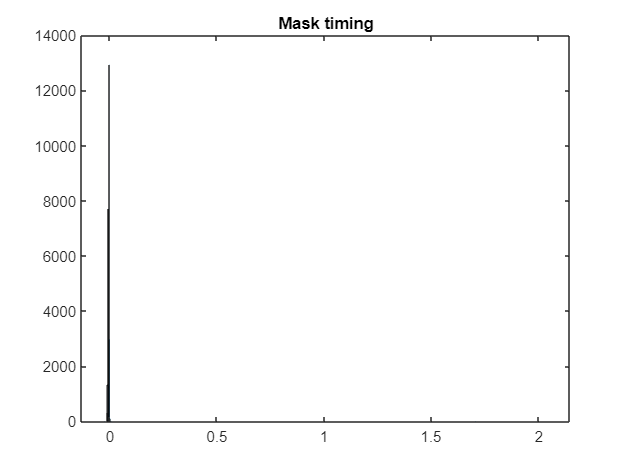

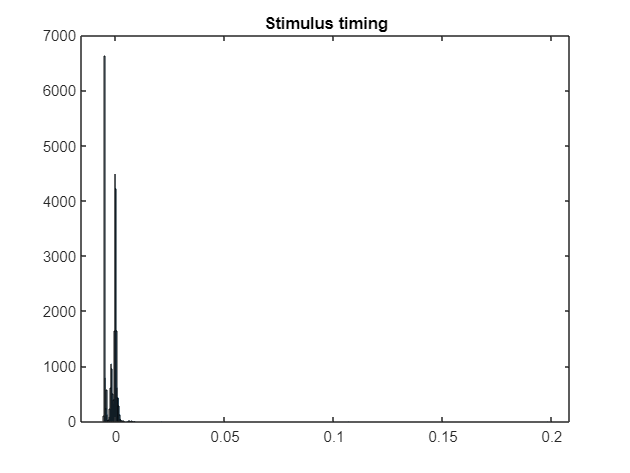

% call costum function to calculate and plot the timing
[timing, d]  = calculate_timing(d);

--- transfrom data (and trial and subject exclusion) ---

% make trial exclusion using a costum function 
d = trial_exclusion(d);

% transform data using a costum function (adds a couple new subtables)
d = transform_data(d);

% make subject exclusion using a costum function 
d = subject_exclusion(d);


% make a backup of d
d2 = d;

%% CHECK If RATING ARE CORRECT

--- performance --- 

% call a costum function to calculate performance
perf = make_perf(d);

--- HISTOGRAMS ---

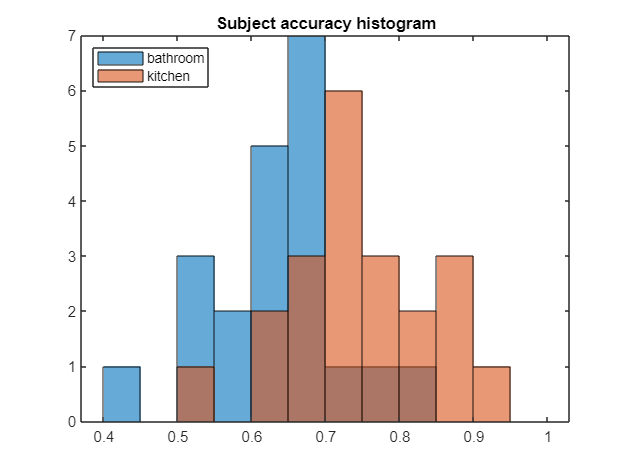

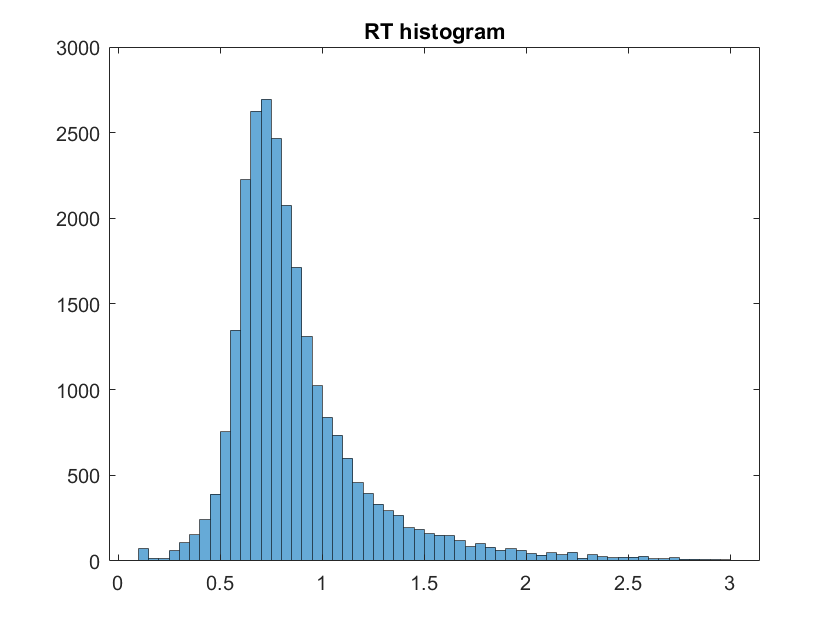

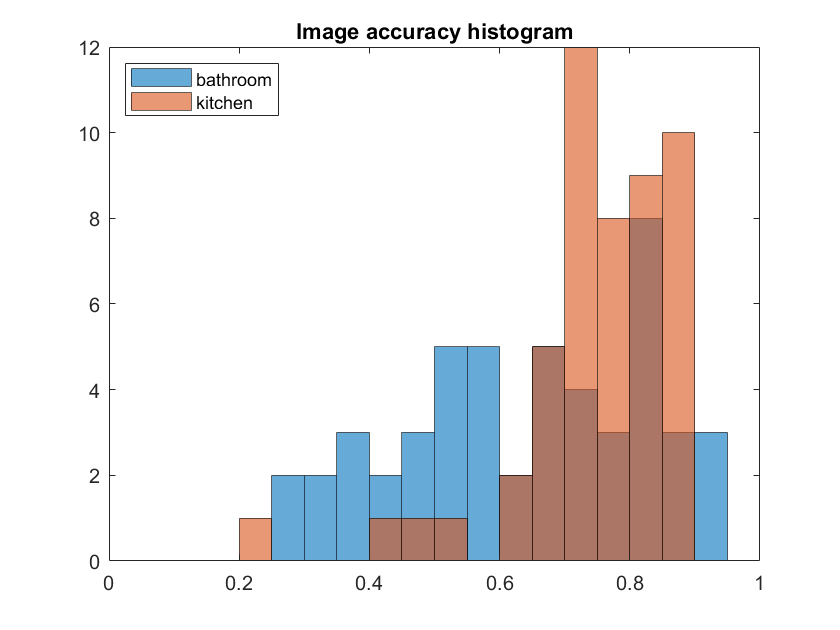

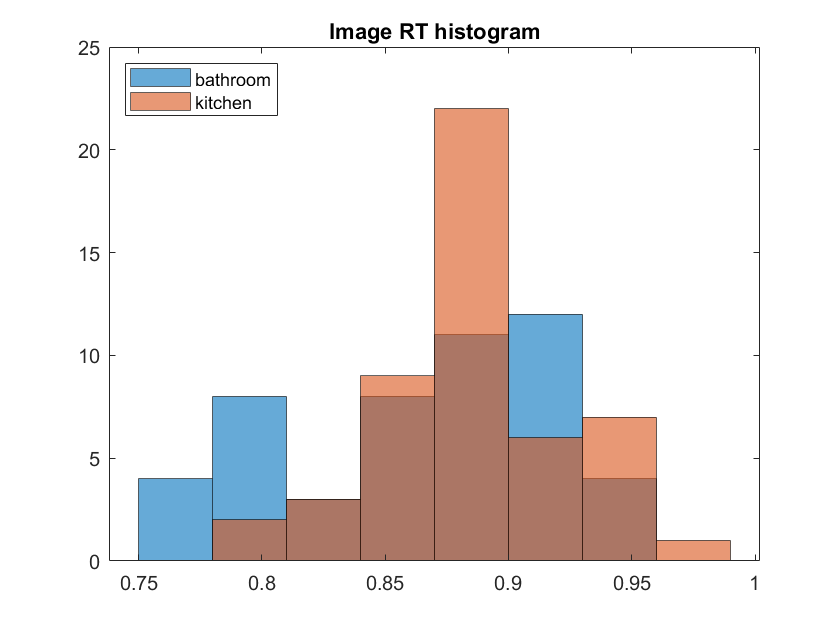

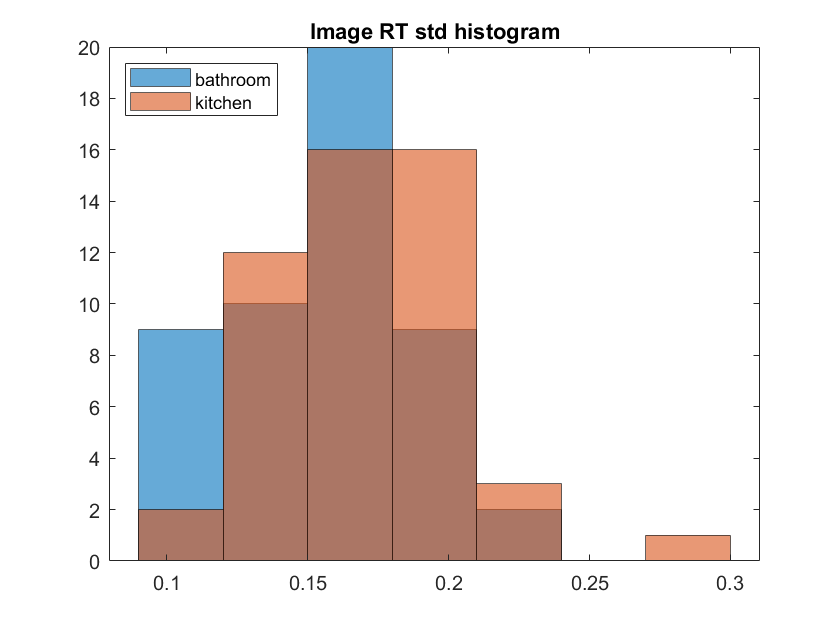

hist_plots = struct with fields:
    hist_sub_acc: [1×1 Histogram]
         hist_RT: [1×1 Histogram]
        hist_acc: [1×1 Histogram]
     hist_img_RT: [1×1 Histogram]
     hist_RT_std: [1×1 Histogram]


% call a costum function to plot histograms
hist_plots = hist_plots(d)

--- rating correlation ---

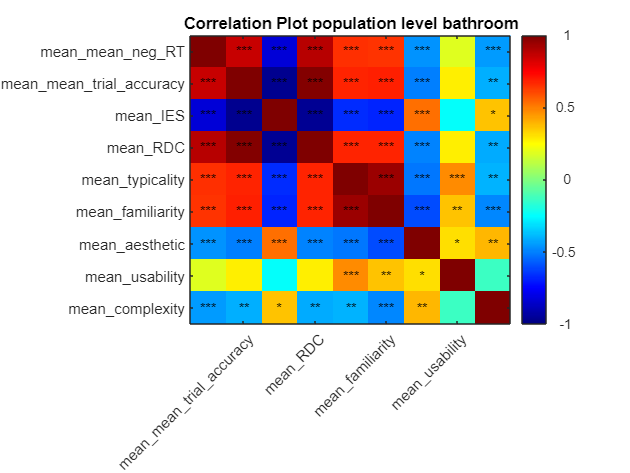

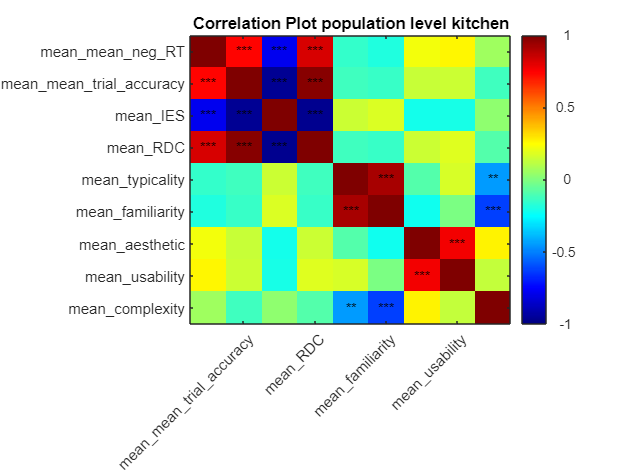

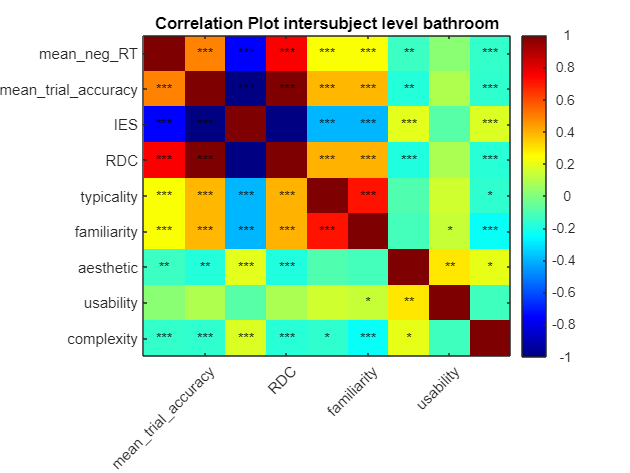

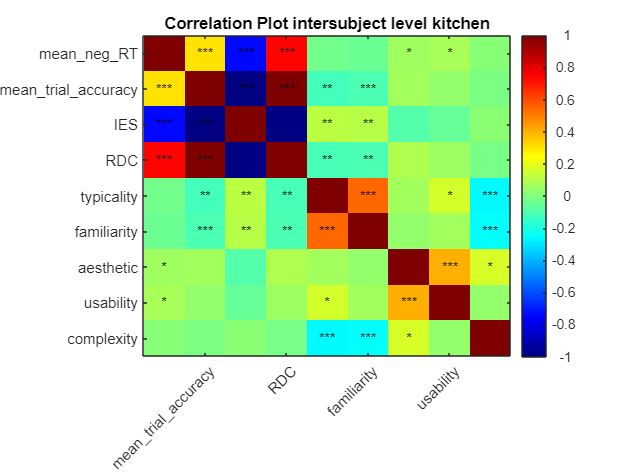

% call a costum function to calculate and plot the correlations of rating on
% population level
[rating_cor_plots, d] = plot_rating_cor(d);

--- intersubject correaltions ---

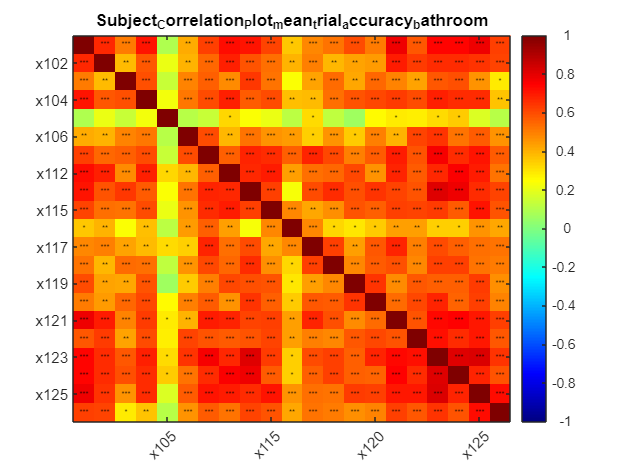

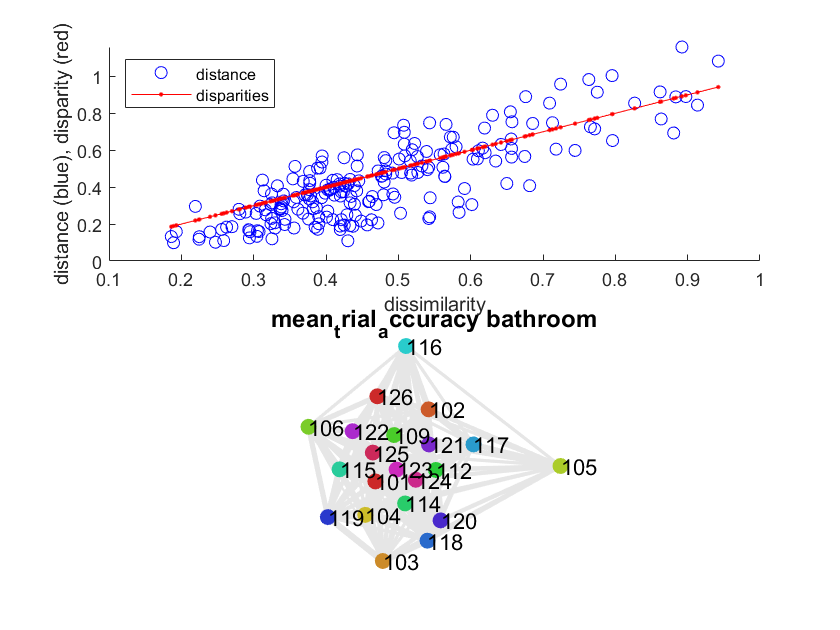

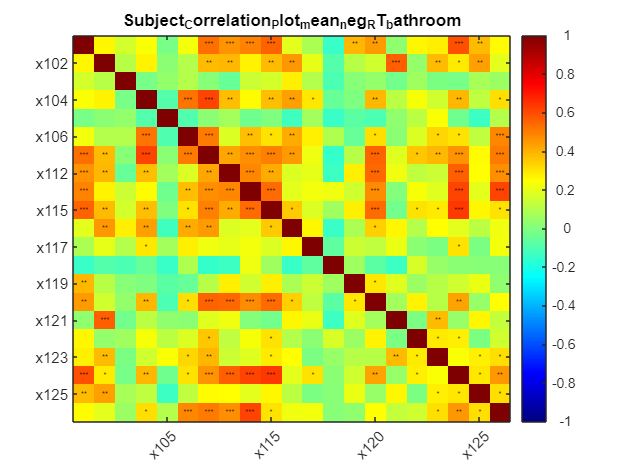

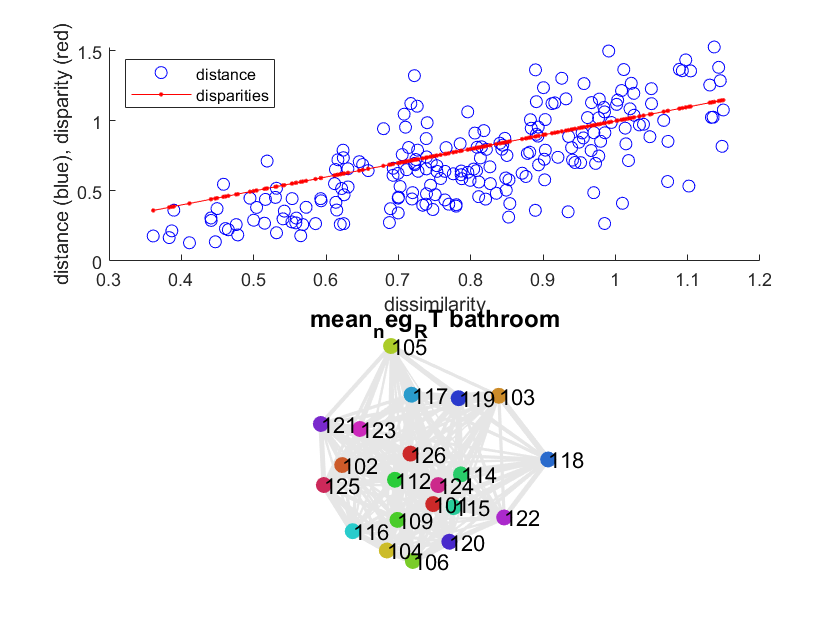

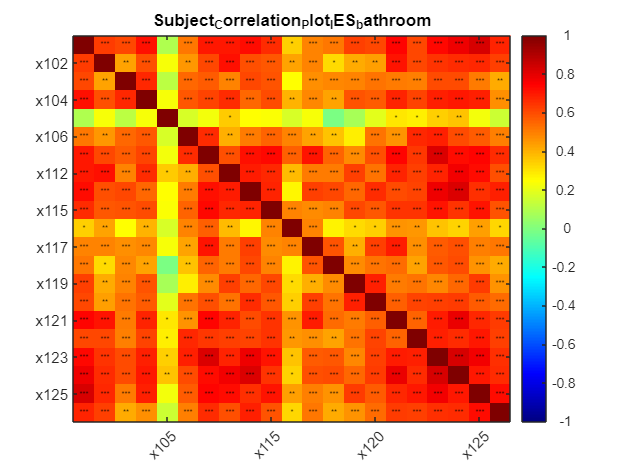

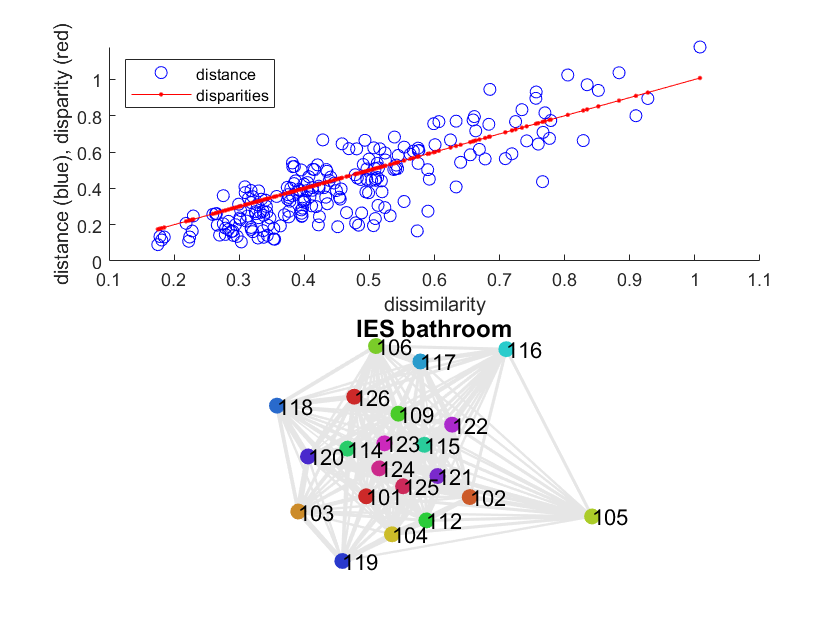

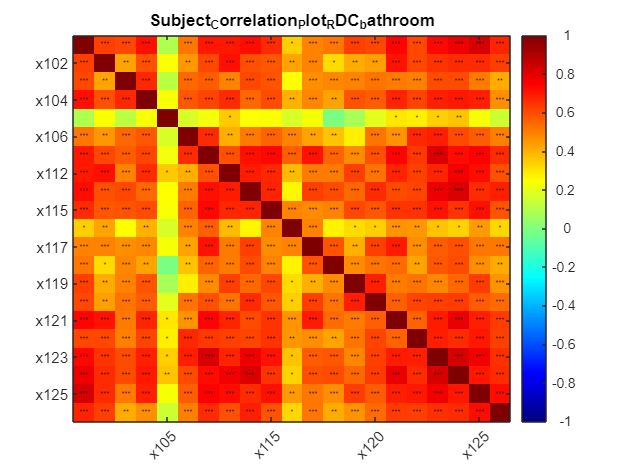

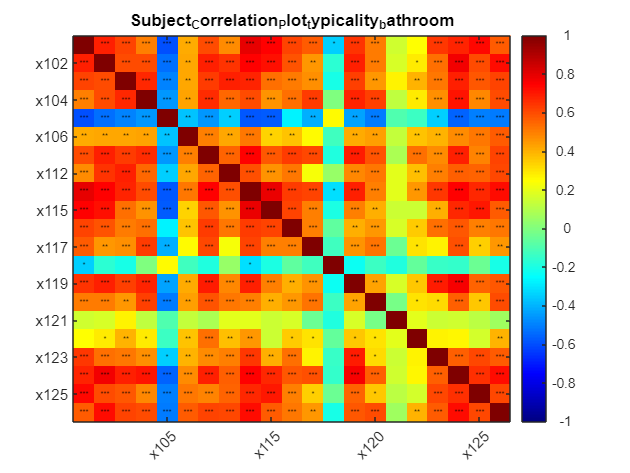

% call a costum function to calculate and plot the correlations of rating between subjects
[cor_plots, d] = intersub_cor(d);

--- task correaltions ---

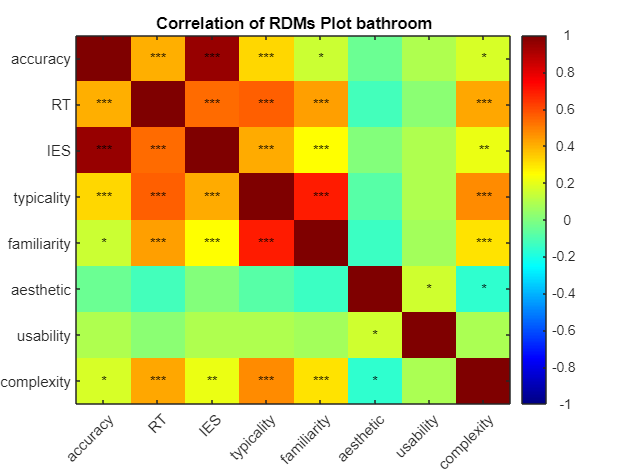

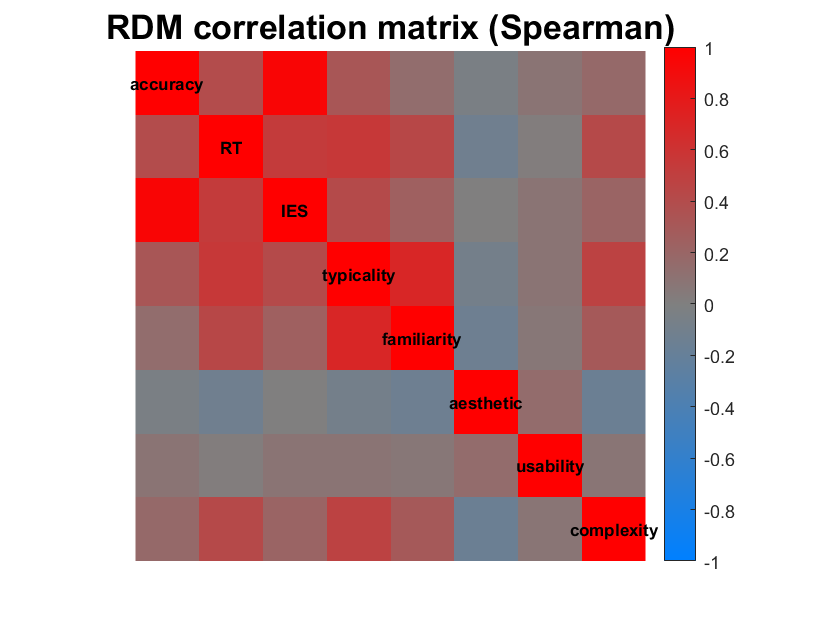

Drawing MDS arrangement for RDMs...
        "MDS of RDMs bathroom" [figure 79000000]


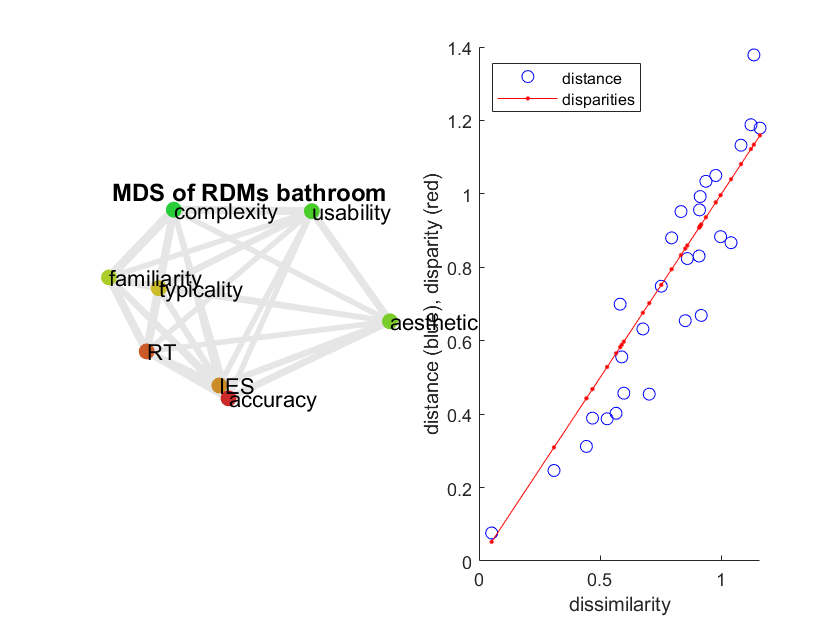

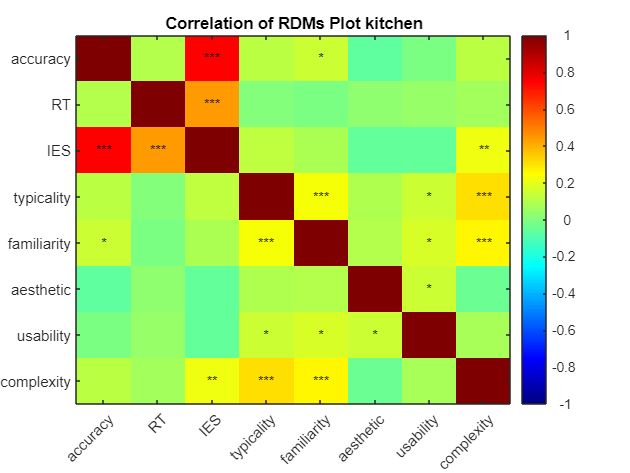

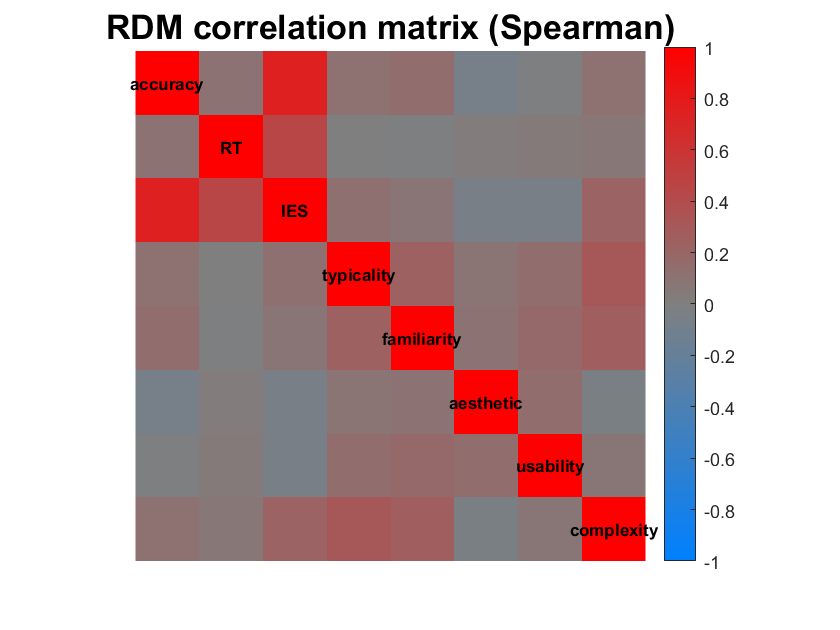

Drawing MDS arrangement for RDMs...
        "MDS of RDMs kitchen" [figure 95000000]


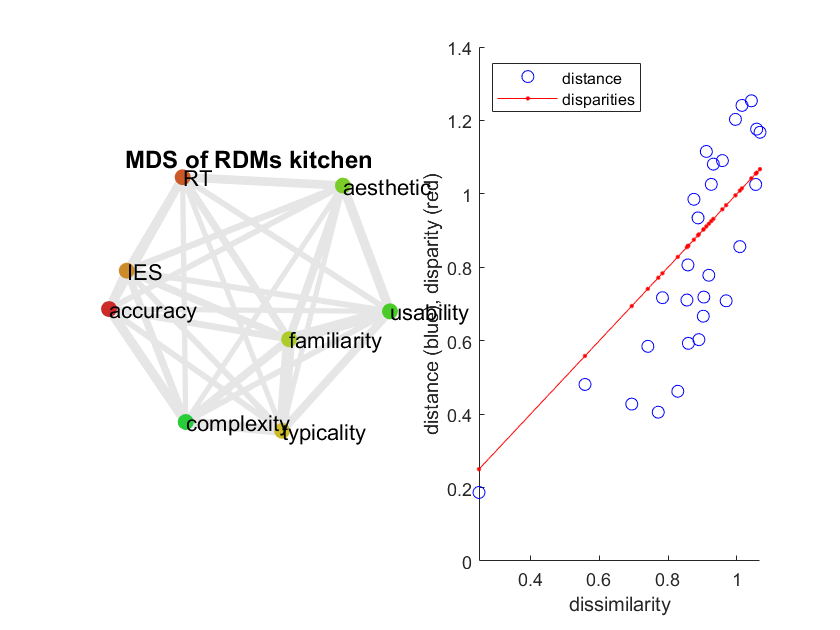

% call a costum function to calculate and plot the correlations between task RDMs
[cor_plots, d] = RDM_of_RDMs(cor_plots, d);

--- combine all measures ---

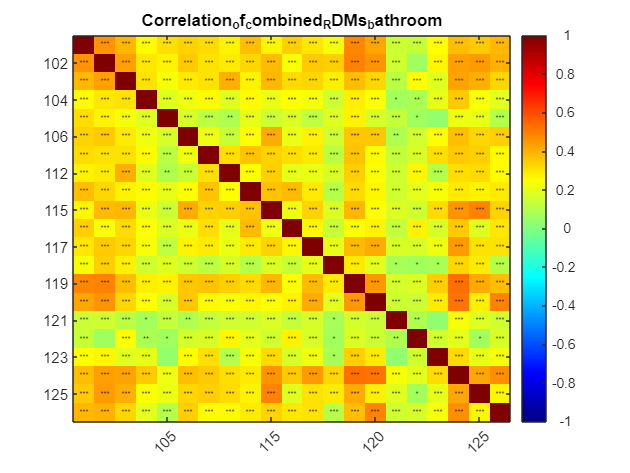

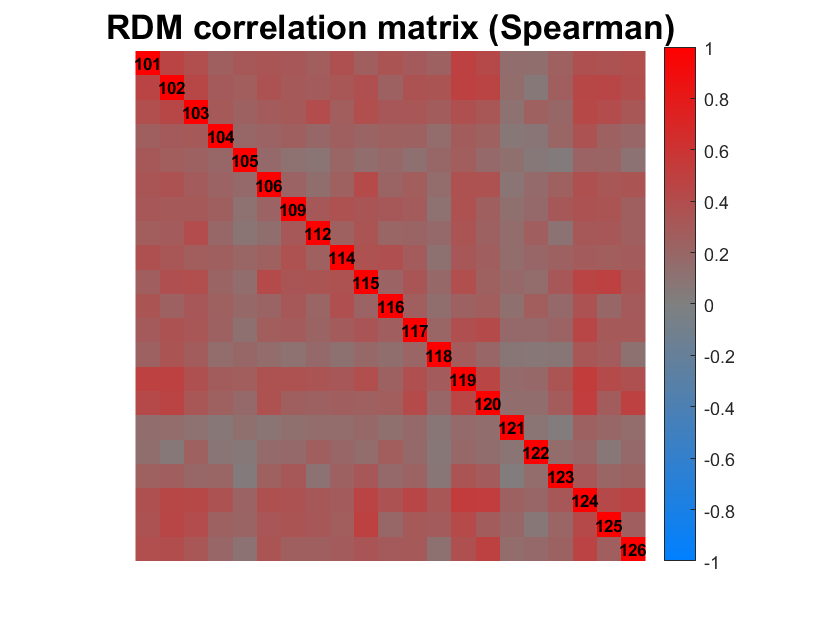

Drawing MDS arrangement for RDMs...
        "MDS of combined RDMs bathroom" [figure 65000000]


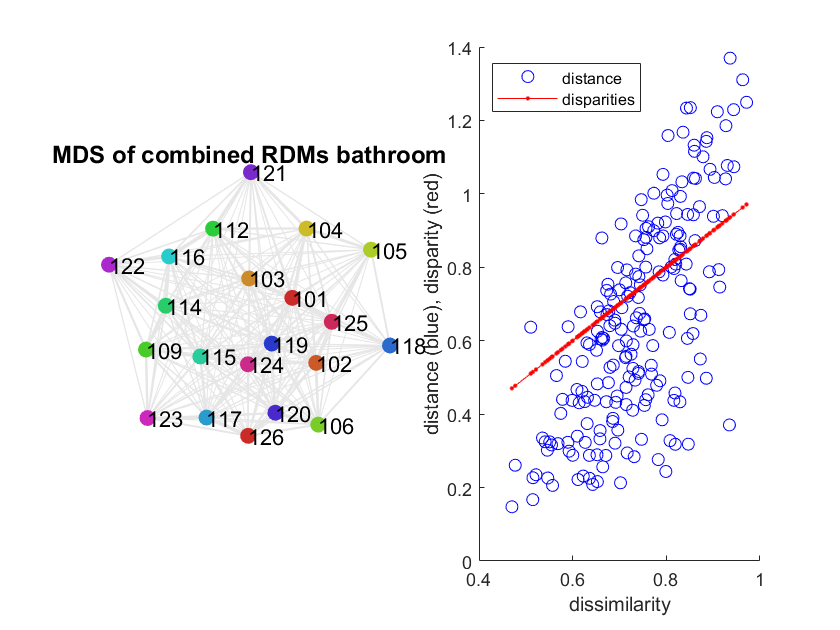

Length of labels do not match matrix dimensions


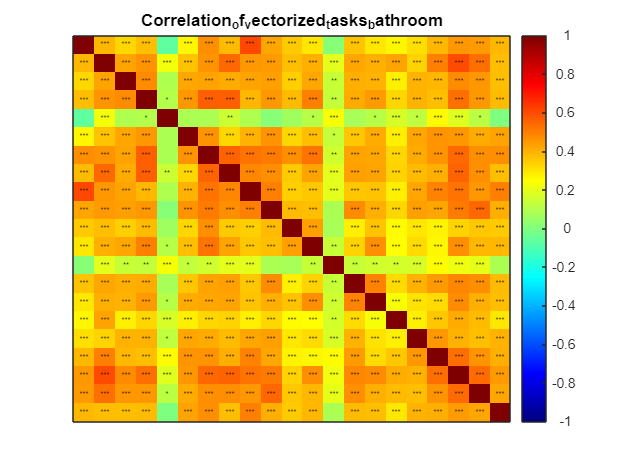

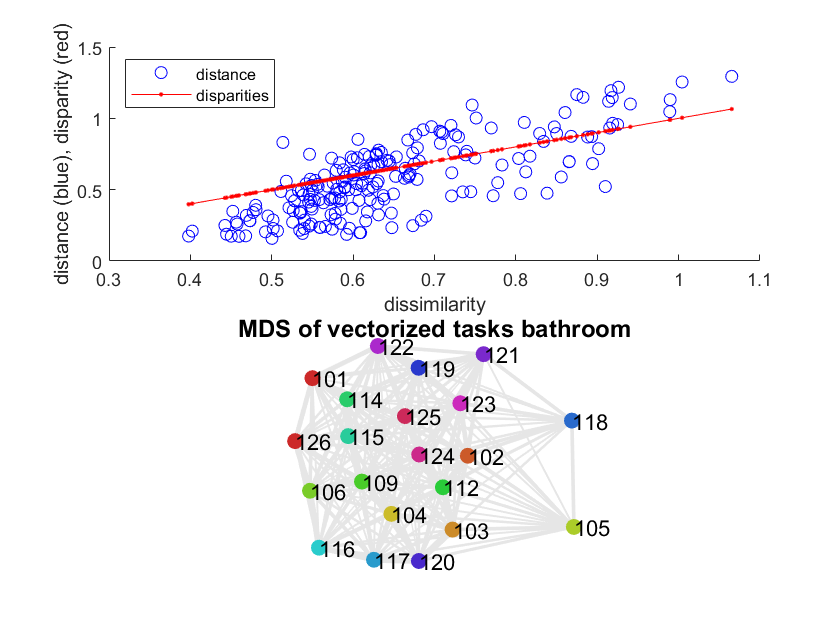

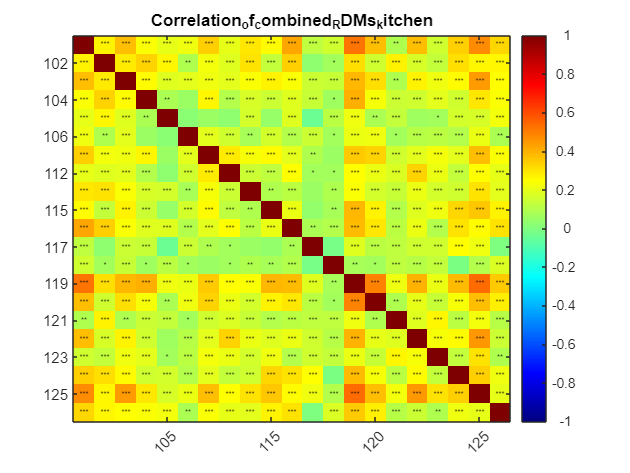

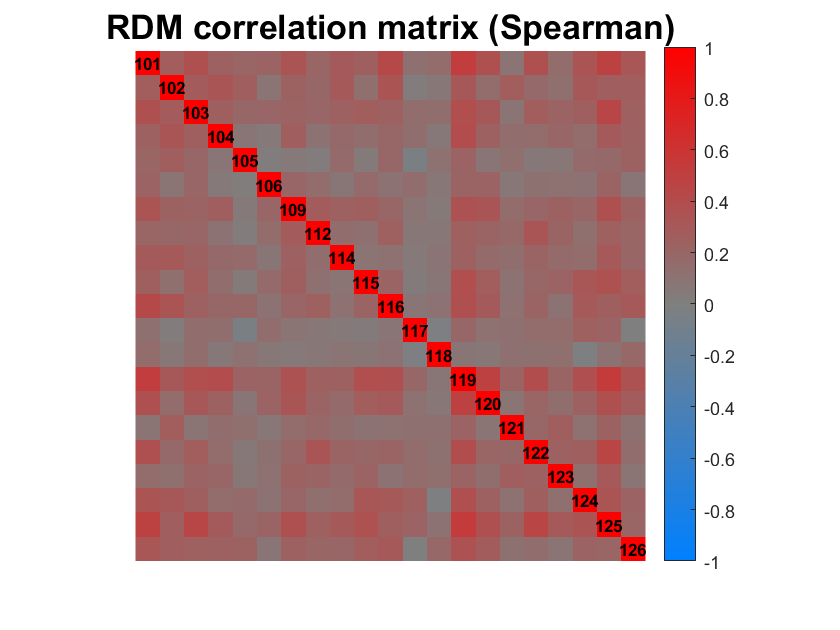

Drawing MDS arrangement for RDMs...
        "MDS of combined RDMs kitchen" [figure 84000000]


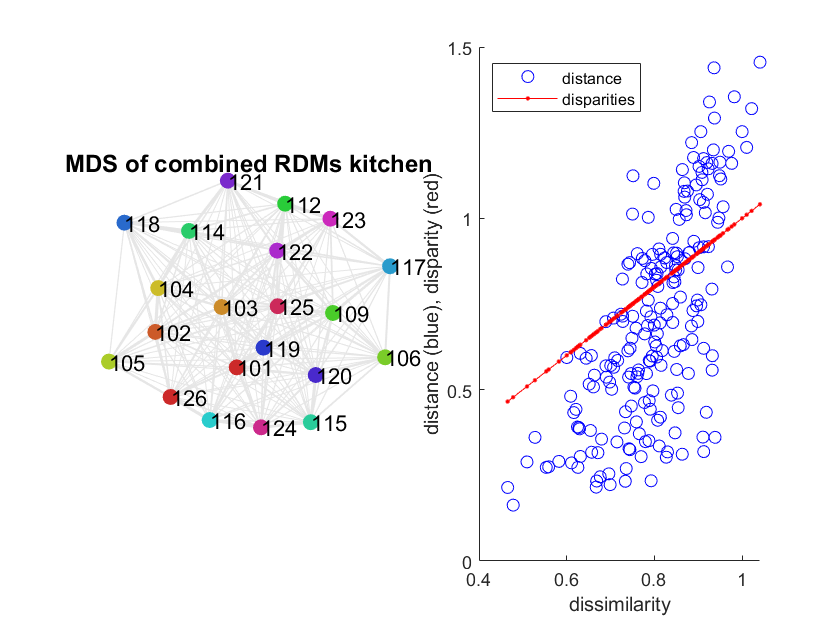

Length of labels do not match matrix dimensions


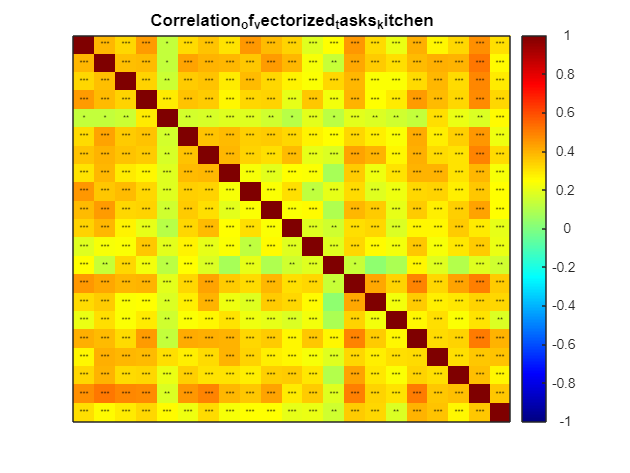

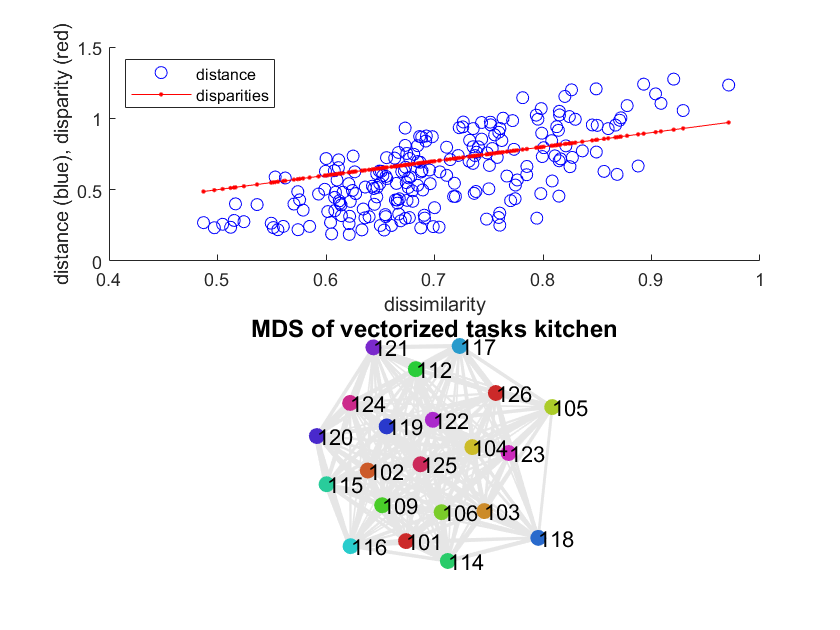

% call a costum function that combines all measures/tasks
[cor_plots, d]  = combined(cor_plots, d);

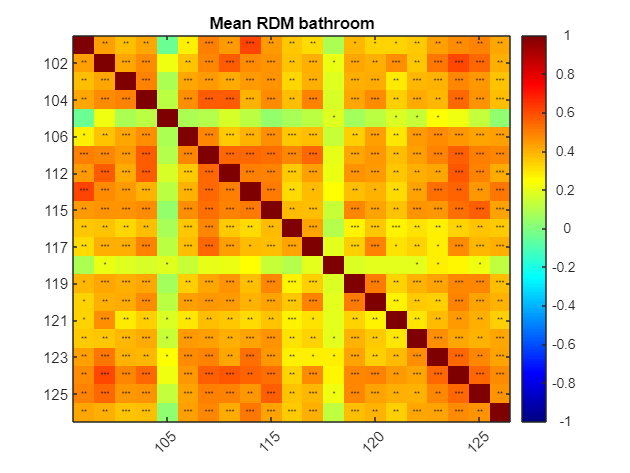

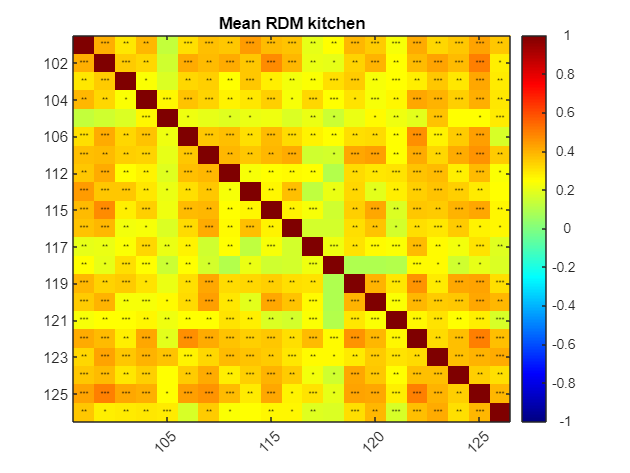

d = make_mean_RDM(d);

% pca(x, 'NumComponents',1)

% userOptions.RDMcorrelationType='Kendall_taua';
% userOptions.RDMrelatednessTest = 'subjectRFXsignedRank';
% userOptions.RDMrelatednessThreshold = 0.05;
% userOptions.RDMrelatednessMultipleTesting = 'FDR';
% userOptions.saveFiguresPDF = 1;
% userOptions.candRDMdifferencesTest = 'subjectRFXsignedRank';
% userOptions.candRDMdifferencesThreshold = 0.05;
% userOptions.candRDMdifferencesMultipleTesting = 'FDR';
% userOptions.plotpValues = '=';
% userOptions.barsOrderedByRDMCorr=true;
% userOptions.resultsPath = userOptions.rootPath;
% userOptions.figureIndex = [14 15];
% userOptions.figure1filename = 'compareRefRDM2candRDMs_barGraph_simulatedITasRef';
% userOptions.figure2filename = 'compareRefRDM2candRDMs_pValues_simulatedITasRef';

% pss = rsa.compareRefRDM2candRDMs(ref_RDM, candRDMs, userOptions);
